# Simscape multibody model og Regbot in balance

initial setup with motor velocity controller this is intended as simulation base for balance control.

close all
clear

## Simulink model name

model='regbot_1mg';

## parameters for REGBOT

motor

RA = 3.3/2;    % ohm (2 motors)
JA = 1.3e-6*2; % motor inertia
LA = 6.6e-3/2; % rotor inductor (2 motors)
BA = 3e-6*2;   % rotor friction
Kemf = 0.0105; % motor constant
Km = Kemf;
% køretøj
NG = 9.69; % gear
WR = 0.03; % wheel radius
Bw = 0.155; % wheel distance
%
% model parts used in Simulink
mmotor = 0.193;   % total mass of motor and gear [kg]
mframe = 0.32;    % total mass of frame and base print [kg]
mtopextra = 0.97 - mframe - mmotor; % extra mass on top (charger and battery) [kg]
mpdist =  0.10;   % distance to lit [m]
% disturbance position (Z)
pushDist = 0.1; % relative to motor axle [m]

## Own REGBOT parameters

% RA = 2*5.5;    % ohm (2 motors)
% JA = 0.0008+0.00055; % motor inertia
% LA = 6.6e-3/2; % rotor inductor (2 motors)
% BA = 0.00000132+0.00000420;   % rotor friction
% Kemf = (0.00782+0.00819)/2; % motor constant
% Km = Kemf;
% % køretøj
% NG = 9.69; % gear
% WR = 0.03; % wheel radius
% Bw = 0.155; % wheel distance
% % model parts used in Simulink
% mmotor = 0.193;   % total mass of motor and gear [kg]
% mframe = 0.32;    % total mass of frame and base print [kg]
% mtopextra = 0.97 - mframe - mmotor; % extra mass on top (charger and battery) [kg]
% mpdist =  0.10;   % distance to lit [m]
% % disturbance position (Z)
% pushDist = 0.1; % relative to motor axle [m]

## Controller design parameters

% Wheel velocity to voltage
N_i_vu = 2;
gamma_vu = 90;

% Tilt to velocity controller
N_i_tv = 10;
gamma_tv = 60;
alpha_tv = 0.00001;

% Pre velocity to tilt controller
N_i_vreft = 4;
gamma_vreft = 360+70;
alpha_vreft = 0.3;

% position to pre velocity controller
gamma_xvref = 360+80;
alpha_xvref = 0.3;

## Initial test parameters

x_test = 1;
x_size = 1;
v_size = 1;

## Sample controller values (initialisation)

K_vu = 15;     % Kp
t_i_vu = 0.05;   % Tau_i
Kffvu = 0;     % feed forward constant
startAngle = 10;  % tilt in degrees at time zero
twvlp = 0.005;    % velocity noise low pass filter time constant (recommended)
K_post = 1;
t_i_post = 1;
t_lead_tv = 0;
t_i_tv = 1;
K_tv = 1;
t_i_vreft = 1;
num_lead_vreft = 0;
den_lead_vreft = 1;
K_vreft = 1;
K_xvref = 1;
num_lead_xvref = 0;
den_lead_xvref = 1;

s = tf('s');

## Estimate transfer function for base system using LINEARIZE

Motor volatge to wheel velocity (wv)

load_system(model);
open_system(model);
% define points in model
ios(1) = linio(strcat(model,'/Limit9v'),1,'openinput');
ios(2) = linio(strcat(model, '/wheel_vel_filter'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gvu = minreal(tf(num, den))

Gvu =
 
                  7.023e05 s^3 + 7.023e08 s^2 - 5.083e07 s - 5.083e10
  -----------------------------------------------------------------------------------
  s^6 + 2418 s^5 + 1.317e06 s^4 + 1.872e08 s^3 + 2.371e09 s^2 - 3.032e10 s - 1.881e11
 
Continuous-time transfer function.
Model Properties


## Transfer function from previous exercise

Gvu = tf(1.811,[1 5.46]) 

Gvu =
 
   1.811
  --------
  s + 5.46
 
Continuous-time transfer function.
Model Properties


## Bodeplot

pole(Gvu)

ans = -5.4600

isstable(Gvu)

ans = logical
   1


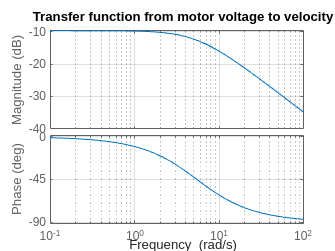

h = figure(100);
bode(Gvu)
grid on
title('Transfer function from motor voltage to velocity')

% saveas(h, 'motor to velocity.png');

## PI-Controller for voltage to velocity

% Design parameters
N_i = 2.5%N_i_vu;

N_i = 2.5000

gamma_m = 90%gamma_vu;

gamma_m = 90

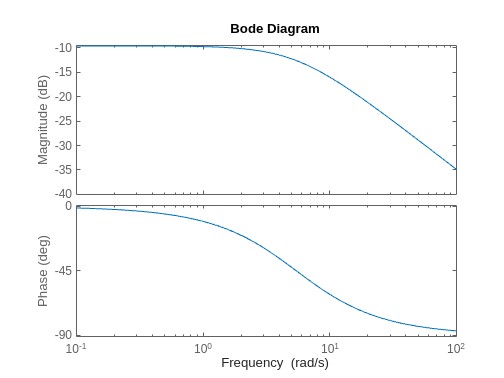


phi_i = rad2deg(-atan(1/N_i));
phi_G = -180+gamma_m-phi_i;

bode(Gvu)

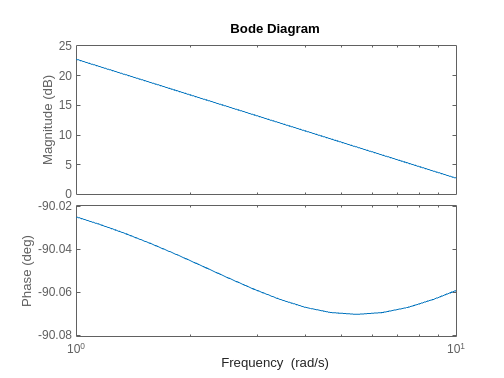


[mag,phase,wout] = bode(Gvu);
omega_c = interp1(squeeze(phase),wout,phi_G);
tau_i = N_i/omega_c;
C_i = tf([tau_i 1],[tau_i 0]);
Kp = 1/abs(freqresp(C_i*Gvu,omega_c*1i));
G_vu_ol = Kp*C_i*Gvu;
G_vu_cl = G_vu_ol/(1+G_vu_ol);
bode(G_vu_ol)

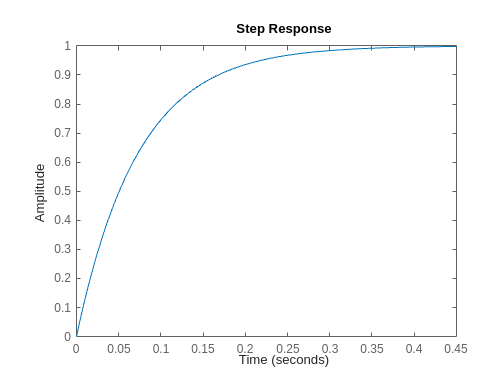

step(G_vu_cl)

N_i = 2;
t_r = 0.2;

omega_c = 2.2/t_r;
tau_i = N_i/omega_c

tau_i = 0.1818

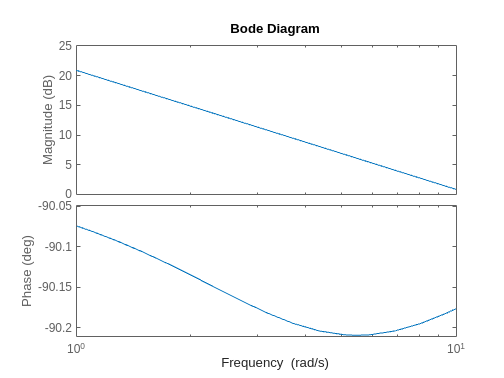

C_i = tf([tau_i 1],[tau_i 0]);
Kp = 1/abs(freqresp(C_i*Gvu,omega_c*1i));
G_vu_ol = Kp*C_i*Gvu;
G_vu_cl = G_vu_ol/(1+G_vu_ol);
bode(G_vu_ol)

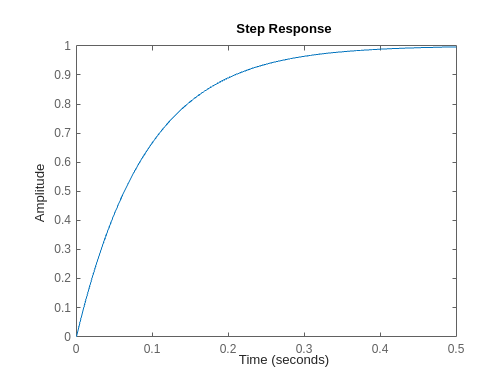

step(G_vu_cl)

## Flush values to model

K_vu = Kp

K_vu = 6.0652

t_i_vu = tau_i

t_i_vu = 0.1818

## **Transfer function from velocity to tilt using linearize**

% define points in model
ios(1) = linio(strcat(model,'/vel_cont'),1,'openinput');
ios(2) = linio(strcat(model, '/tilt_angle'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gtv = minreal(tf(num, den))

Gtv =
 
                 -2.383e05 s^4 - 3.083e08 s^3 - 5.355e10 s^2 - 2.854e11 s - 8.543e08
  --------------------------------------------------------------------------------------------------
  s^7 + 2418 s^6 + 1.317e06 s^5 + 1.915e08 s^4 + 6.654e09 s^3 - 7.203e09 s^2 - 4.981e11 s - 1.696e12
 
Continuous-time transfer function.


h = figure(100)

h =   Figure (100) with properties:

      Number: 100
        Name: ''
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


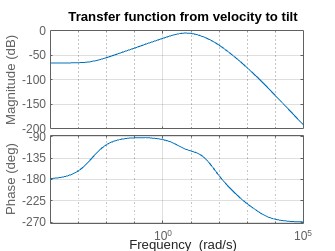

bode(-Gtv)
grid on
title('Transfer function from velocity to tilt')

[mag,phase,wout]=bode(Gtv);

## Post-Integrator

[gpeak,fpeak] = getPeakGain(-Gtv)

gpeak = 0.5570

fpeak = 6.6395

tau_i = 1/fpeak

tau_i = 0.1506

C_pi = -(tau_i*s+1)/(tau_i*s)

C_pi =
 
  -0.1506 s - 1
  -------------
    0.1506 s
 
Continuous-time transfer function.
Model Properties


G_post=Gtv*C_pi

G_post =
 
                3.589e04 s^5 + 4.667e07 s^4 + 8.374e09 s^3 + 9.654e10 s^2 + 2.855e11 s + 8.543e08
  --------------------------------------------------------------------------------------------------------------
  0.1506 s^8 + 364.2 s^7 + 1.983e05 s^6 + 2.884e07 s^5 + 1.002e09 s^4 - 1.085e09 s^3 - 7.502e10 s^2 - 2.554e11 s
 
Continuous-time transfer function.


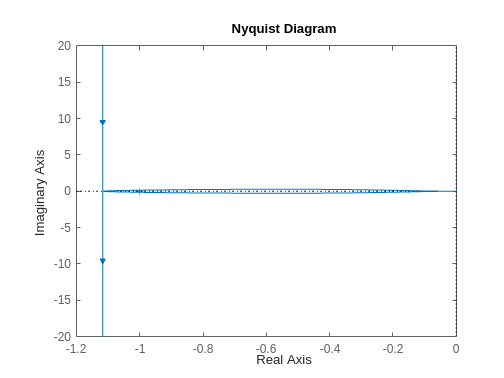

nyquist(G_post)

G_post_cl=minreal(G_post/(1+G_post))

G_post_cl =
 
                  2.383e05 s^5 + 3.099e08 s^4 + 5.56e10 s^3 + 6.41e11 s^2 + 1.896e12 s + 5.672e09
  ----------------------------------------------------------------------------------------------------------------
  s^8 + 2418 s^7 + 1.317e06 s^6 + 1.917e08 s^5 + 6.964e09 s^4 + 4.84e10 s^3 + 1.429e11 s^2 + 2.002e11 s + 5.672e09
 
Continuous-time transfer function.


isstable(G_post_cl)

ans = logical
   1


## Flush values to Simulink

K_post = -1

K_post = -1

t_i_post=tau_i

t_i_post = 0.1506

## Tilt to velocity controller PI-lead

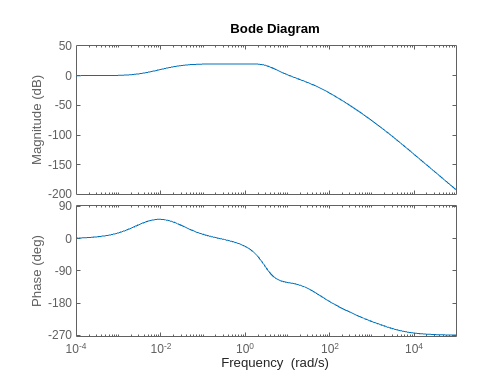

bode(G_post_cl)

% Design parameters
N_i =6%N_i_tv;

N_i = 6

gamma_m = 80%gamma_tv;

gamma_m = 80

alpha = 0.001%alpha_tv;

alpha = 1.0000e-03



phi_i = rad2deg(-atan(1/N_i));
phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

phi_G = gamma_m - phi_i - phi_m - 180;
[mag,phase,wout] = bode(G_post_cl);
omega_c = interp1(squeeze(phase),wout,phi_G);

tau_D = 1/(omega_c*sqrt(alpha));
tau_i = N_i/omega_c;

C_i = tf([tau_i 1],[tau_i 0])

C_i =
 
  0.05759 s + 1
  -------------
    0.05759 s
 
Continuous-time transfer function.
Model Properties


C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
   0.3035 s + 1
  ---------------
  0.0003035 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_i*C_D*G_post_cl),omega_c);
Kp = 1/mag;

G_tv_ol = minreal(Kp*C_i*C_D*G_post_cl)

G_tv_ol =
 
            2.399e08 s^7 + 3.169e11 s^6 + 6.244e13 s^5 + 1.82e15 s^4 + 1.844e16 s^3 + 7.636e16 s^2 + 1.093e17 s + 3.267e14
  -----------------------------------------------------------------------------------------------------------------------------------
  s^10 + 5713 s^9 + 9.284e06 s^8 + 4.53e09 s^7 + 6.385e11 s^6 + 2.299e13 s^5 + 1.596e14 s^4 + 4.71e14 s^3 + 6.597e14 s^2 + 1.869e13 s
 
Continuous-time transfer function.


G_tv_cl = minreal(G_tv_ol/(1+G_tv_ol))

G_tv_cl =
 
                  2.399e08 s^7 + 3.169e11 s^6 + 6.244e13 s^5 + 1.82e15 s^4 + 1.844e16 s^3 + 7.636e16 s^2 + 1.093e17 s + 3.267e14
  -----------------------------------------------------------------------------------------------------------------------------------------------
  s^10 + 5713 s^9 + 9.284e06 s^8 + 4.77e09 s^7 + 9.554e11 s^6 + 8.543e13 s^5 + 1.979e15 s^4 + 1.891e16 s^3 + 7.702e16 s^2 + 1.093e17 s + 3.267e14
 
Continuous-time transfer function.


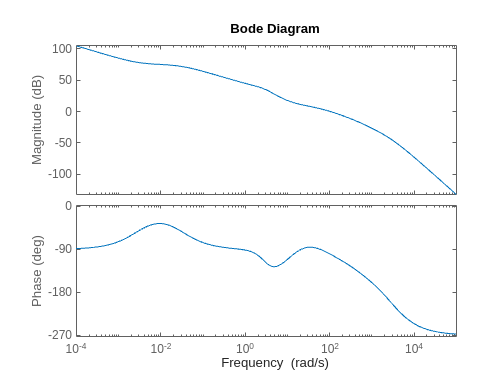


bode(G_tv_ol)

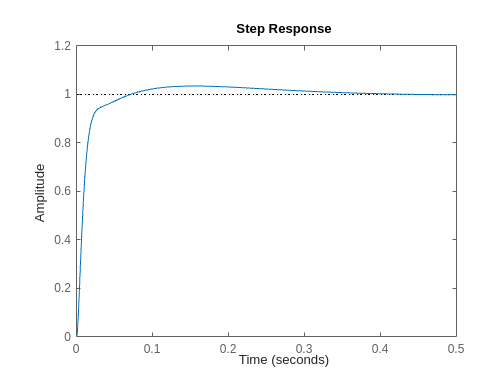

step(G_tv_cl)

## Flush values to simulink

t_i_post

t_i_post = 0.1506

t_lead_tv = tau_D

t_lead_tv = 0.3035

t_i_tv = tau_i

t_i_tv = 0.0576

K_tv = Kp

K_tv = 1.0068

## Transfer function from reference tilt to velocity using linearize

% define points in model
ios(1) = linio(strcat(model,'/tilt_ref'),1,'openinput');
ios(2) = linio(strcat(model, '/wheel_vel_filter'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
G_vreft = minreal(tf(num, den))

G_vreft =
 
                -4.289e06 s^6 - 4.415e09 s^5 - 1.273e11 s^4 - 7.438e11 s^3 + 6.515e12 s^2 + 7.696e13 s + 1.968e14
  -----------------------------------------------------------------------------------------------------------------------------
  s^9 + 2418 s^8 + 1.39e06 s^7 + 2.834e08 s^6 + 2.132e10 s^5 + 5.22e11 s^4 + 5.41e12 s^3 + 2.318e13 s^2 + 3.318e13 s + 9.916e10
 
Continuous-time transfer function.


## Reference tilt to velocity controller

isstable(G_vreft)

ans = logical
   1


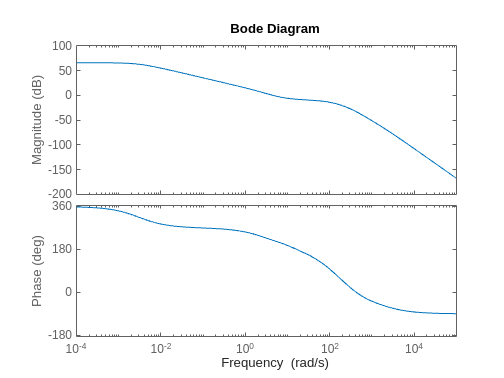

bode(G_vreft)



% Design parameters
N_i = 2%N_i_vreft;

N_i = 2

gamma_m = 60+360%gamma_vreft;

gamma_m = 420

alpha = 0.4 %alpha_vreft;

alpha = 0.4000



phi_i = rad2deg(-atan(1/N_i));
phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

phi_G = gamma_m - phi_i - phi_m - 180;
[mag,phase,wout] = bode(G_vreft);
omega_c = interp1(squeeze(phase),wout,phi_G);

tau_D = 1/(omega_c*sqrt(alpha));
tau_i = N_i/omega_c;

C_i = tf([tau_i 1],[tau_i 0])

C_i =
 
  1.088 s + 1
  -----------
    1.088 s
 
Continuous-time transfer function.
Model Properties


C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
  0.8599 s + 1
  ------------
  0.3439 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_i*C_D*G_vreft),omega_c);
Kp = 1/mag;

G_vreft_ol = minreal(Kp*C_i*C_D*G_vreft)

G_vreft_ol =
 
              -2.073e06 s^8 - 2.139e09 s^7 - 6.598e10 s^6 - 4.9e11 s^5 + 2.335e12 s^4 + 4.338e13 s^3 + 1.76e14 s^2 + 2.379e14 s + 1.017e14
  ----------------------------------------------------------------------------------------------------------------------------------------------------
  s^11 + 2421 s^10 + 1.397e06 s^9 + 2.874e08 s^8 + 2.215e10 s^7 + 5.84e11 s^6 + 6.927e12 s^5 + 3.891e13 s^4 + 1.006e14 s^3 + 9.657e13 s^2 + 2.883e11 s
 
Continuous-time transfer function.


G_vreft_cl = minreal(G_vreft_ol/(1+G_vreft_ol))

G_vreft_cl =
 
                   -2.073e06 s^8 - 2.139e09 s^7 - 6.598e10 s^6 - 4.9e11 s^5 + 2.335e12 s^4 + 4.338e13 s^3 + 1.76e14 s^2 + 2.379e14 s + 1.017e14
  ---------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^11 + 2421 s^10 + 1.397e06 s^9 + 2.854e08 s^8 + 2.001e10 s^7 + 5.18e11 s^6 + 6.437e12 s^5 + 4.124e13 s^4 + 1.439e14 s^3 + 2.726e14 s^2 + 2.382e14 s + 1.017e14
 
Continuous-time transfer function.


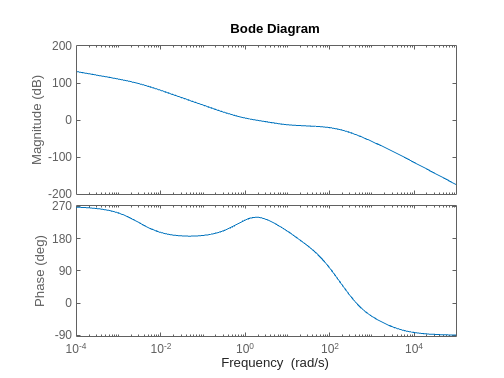


bode(G_vreft_ol)

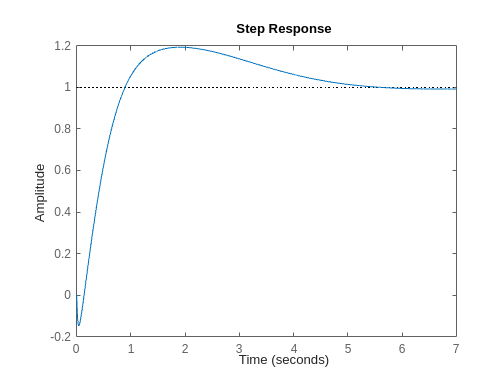

step(G_vreft_cl)

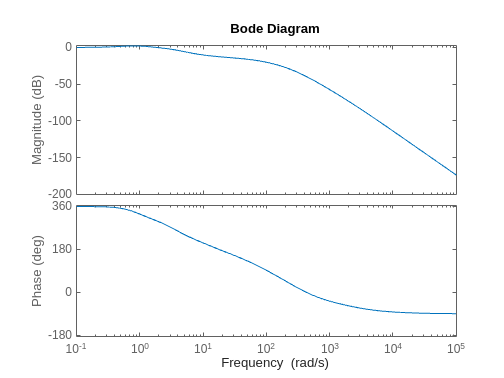

bode(G_vreft_cl)

## Flush values to simulink

t_i_vreft = tau_i

t_i_vreft = 1.0876

[num_lead_vreft,den_lead_vreft] = tfdata(C_D,'v')

num_lead_vreft =     0.8599    1.0000


den_lead_vreft =     0.3439    1.0000


K_vreft = Kp

K_vreft = 0.1934

## Transfer function from vel_pre to x

% define points in model
ios(1) = linio(strcat(model,'/vel_ref'),1,'openinput');
ios(2) = linio(strcat(model, '/x_pos'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
G_xvref = minreal(tf(num, den))

G_xvref =
 
               -4146 s^9 - 5.115e06 s^8 - 9.972e08 s^7 - 2.925e10 s^6 - 2.418e11 s^5 + 7.046e11 s^4 + 1.997e13 s^3 + 1.025e14 s^2 + 1.997e14 s + 1.204e14
  --------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^12 + 2421 s^11 + 1.397e06 s^10 + 2.896e08 s^9 + 2.43e10 s^8 + 5.532e11 s^7 + 6.184e12 s^6 + 3.857e13 s^5 + 1.395e14 s^4 + 2.794e14 s^3 + 2.615e14 s^2 + 1.204e14 s
 
Continuous-time transfer function.


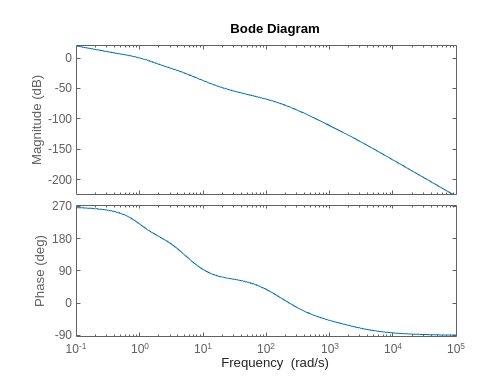

bode(G_xvref)

isstable(G_xvref)

ans = logical
   0


pole(G_xvref)

ans = 1.0e+03 *

   0.0000 + 0.0000i
  -1.6922 + 0.0000i
  -0.4143 + 0.0000i
  -0.1436 + 0.0590i
  -0.1436 - 0.0590i
  -0.0072 + 0.0044i
  -0.0072 - 0.0044i
  -0.0050 + 0.0000i
  -0.0034 + 0.0029i
  -0.0034 - 0.0029i




% Design parameters
gamma_m = 60+360%gamma_xvref;

gamma_m = 420

alpha = 0.1%alpha_xvref;

alpha = 0.1000


phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

phi_G = gamma_m - phi_m - 180;
[mag,phase,wout] = bode(G_xvref);
omega_c = interp1(squeeze(phase),wout,phi_G);

tau_D = 1/(omega_c*sqrt(alpha));

C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
  1.539 s + 1
  ------------
  0.1539 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_D*G_xvref),omega_c);
Kp = 1/mag;

G_xvref_ol = minreal(Kp*C_D*G_xvref)

G_xvref_ol =
 
            -4.386e04 s^10 - 5.413e07 s^9 - 1.058e10 s^8 - 3.163e11 s^7 - 2.759e12 s^6 + 5.792e12 s^5 + 2.161e14 s^4 + 1.221e15 s^3 + 2.817e15 s^2 + 2.646e15 s + 8.271e14
  -----------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^13 + 2428 s^12 + 1.412e06 s^11 + 2.987e08 s^10 + 2.618e10 s^9 + 7.111e11 s^8 + 9.778e12 s^7 + 7.874e13 s^6 + 3.9e14 s^5 + 1.185e15 s^4 + 2.077e15 s^3 + 1.819e15 s^2 + 7.818e14 s
 
Continuous-time transfer function.


G_xvref_cl = minreal(G_xvref_ol/(1+G_xvref_ol))

G_xvref_cl =
 
                   -4.386e04 s^12 - 5.464e07 s^11 - 1.121e10 s^10 - 4.4e11 s^9 - 6.75e12 s^8 - 3.634e13 s^7 + 1.927e14 s^6 + 3.901e15 s^5 + 2.395e16 s^4 + 7.502e16 s^3 + 1.234e17 s^2 + 9.597e16 s + 2.702e16
  ------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^15 + 2439 s^14 + 1.44e06 s^13 + 3.15e08 s^12 + 2.962e10 s^11 + 1.011e12 s^10 + 1.839e13 s^9 + 2.079e14 s^8 + 1.581e15 s^7 + 8.446e15 s^6 + 3.238e16 s^5 + 8.844e16 s^4 + 1.646e17 s^3 + 1.918e17 s^2 + 1.215e17 s + 2.702e16
 
Continuous-time transfer function.


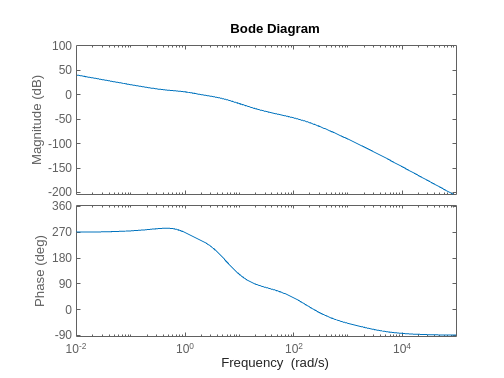


bode(G_xvref_ol)

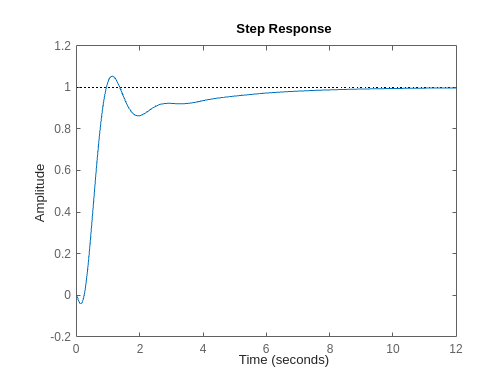

step(G_xvref_cl)

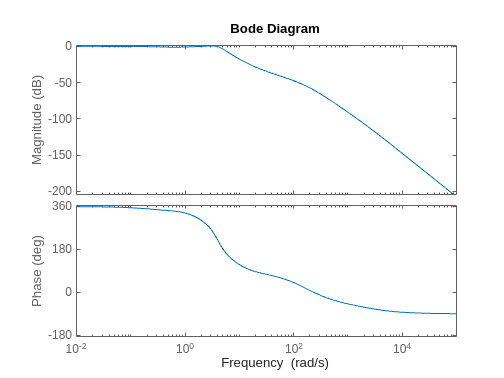

bode(G_xvref_cl)

## Flush values to Simulink

[num_lead_xvref,den_lead_xvref] = tfdata(C_D,'v')

num_lead_xvref =     1.5393    1.0000


den_lead_xvref =     0.1539    1.0000


K_xvref = Kp

K_xvref = 1.0579

## X step test

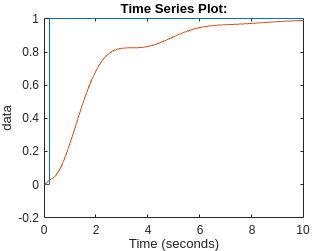

x_test = 1;
x_size = 1;

regsim = sim(model,10);

figure(1);
plot(regsim.ref);
hold on;
plot(regsim.x_pos);
hold off;

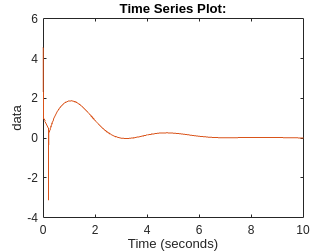


figure(2)
plot(regsim.u)
hold on;
plot(regsim.ulim);
hold off;

## v step size

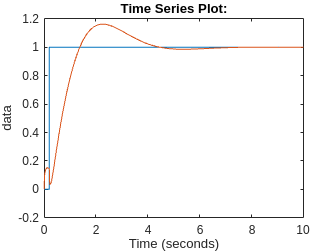

x_test = 0;
v_size = 1;

regsim = sim(model,10);

figure(1);
plot(regsim.vref);
hold on;
plot(regsim.vel);
hold off;

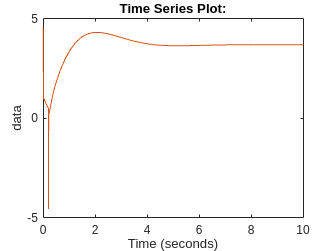


figure(2)
plot(regsim.u)
hold on;
plot(regsim.ulim);
hold off;

## Print controller values

K_vu

K_vu = 9.9243

t_i_vu

t_i_vu = 0.2652

K_post

K_post = -1

t_i_post

t_i_post = 0.1332

t_lead_tv

t_lead_tv = 0.1512

t_i_tv

t_i_tv = 0.0383

K_tv

K_tv = 2.5826

t_i_vreft

t_i_vreft = 1.2734

num_lead_vreft

num_lead_vreft =     0.7610    1.0000


den_lead_vreft

den_lead_vreft =     0.5327    1.0000


K_vreft

K_vreft = 0.1970

K_xvref

K_xvref = 0.7130

num_lead_xvref

num_lead_xvref =     1.1306    1.0000


den_lead_xvref

den_lead_xvref =     0.5653    1.0000
